clear all;close all;

% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1014_0.CSV');  %cigu 0.7m 12v runtest
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1029_8.CSV');  %DOHZ 2~10hz 0.7m 12v 24v
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_0.CSV');  %DOHZ h1 test
mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_1.CSV');  %DOHZ 3、4hz 0.7m 6v 12v 24v

% mo=mo(87000:95000,:);
moo=mo;

mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo(a1-200:a1,:)=[];
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,3:5);  %無校正
acc2 = mo(:,6:8);  %無校正
gyr1=mo(:,9:11);
gyr2=mo(:,12:14);
m = mo(:,15:17); %%%% to guess
temp=moo(:,20:23);
h1=moo(:,18);
h2=moo(:,19);
magt=moo(:,20);
imu1t=moo(:,21);
imu2t=moo(:,22);
mcut=moo(:,23);
f=moo(:,24);
delay=moo(:,25);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
aG2=sqrt(ax2.^2+ay2.^2+az2.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2)*0.01;
GG2=sqrt(gyr2(:,1).^2+gyr2(:,2).^2+gyr2(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
% mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

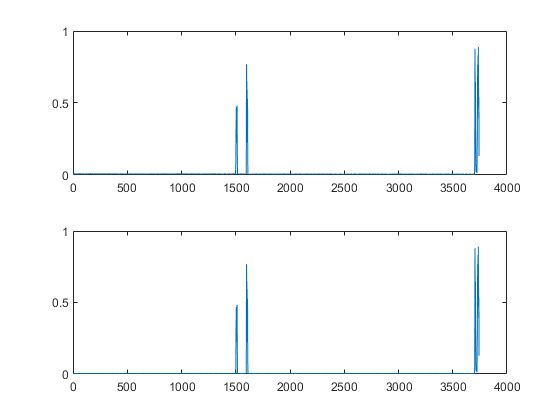

close all
figure(1)
subplot(2,1,1)
plot(t,smooth(GG,200))
subplot(2,1,2)
plot(t,smooth(GG2,200))

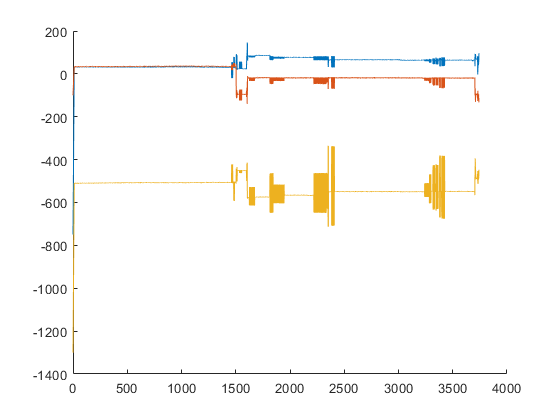


figure(2)
% plot(t,m)
hold on
plot(t,m(:,1)+50)
plot(t,m(:,2)-100)
plot(t,m(:,3)-500)
hold off

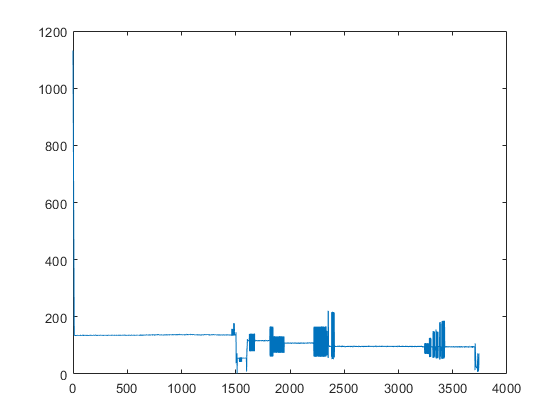


figure(3)
plot(t,mm4)

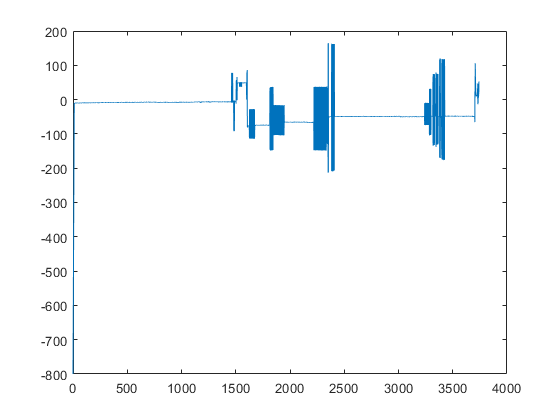


figure(4)
% plot(t,m(:,1))
% plot(t,m(:,2))
plot(t,m(:,3))

close all

% tt1=327.251; %開始時間 teensy
% tt1=327.489; %開始時間
% tt1=11255.749; %開始時間
tt1=11255.963; %開始時間
% 1.1244228
hz=2; %hz
long=300; %時長
tn=tt1+long;
ticks(1:long)=0;
for i=1:long
    ticks(i)=tt1+(i-1)*(1/hz);
end
tickss=ticks;


for i=1:long
    [~,tickss(i)]=min(abs(t-ticks(i)));
end

paxis=1;

figure(1)
hold on
plot(t,m(:,paxis))

for i=1:long
    plot(ticks(i),m(tickss(i),paxis),'ro')
end

hold off

figure(2)
hold on
% plot(t,m)
plot(t,m(:,1)+50)
plot(t,m(:,2)-100)
plot(t,m(:,3)-500)


for i=1:long
%     plot(ticks(i),m(tickss(i),:),'ro')
    plot(ticks(i),m(tickss(i),1)+50,'ro')
    plot(ticks(i),m(tickss(i),2)-100,'ro')
    plot(ticks(i),m(tickss(i),3)-500,'ro')
    
end

hold off



% power_sensor_90393
close all
% mpo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\temp2\data\0508_7.CSV');  %2 coil test
mpo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\temp2\data\0508_8.CSV');  %2 coil test
mpt=mpo(:,1);
mprt=mpo(:,2);
mpm=mpo(:,[3:5]);

hold on
plot(mpt,mpm(:,1))
plot(mpt,mpm(:,2)-50)
plot(mpt,mpm(:,3)-500)
hold off


% tag1=300000;tag2=400000; %v3.3
tag1=250000;tag2=270000; %v3.2
stdd=std(mo(tag1:tag2,[2:16])) %看標準差
disp("acc1")
std(acc1(tag1:tag2,:)) %看標準差
disp("acc2")
std(acc2(tag1:tag2,:)) %看標準差
disp("gry1")
std(gyr1(tag1:tag2,:)) %看標準差
disp("gry2")
std(gyr2(tag1:tag2,:)) %看標準差
disp("m")
std(m(tag1:tag2,:)) %看標準差
disp("aG")
std(aG(tag1:tag2,:)) %看標準差
disp("aG2")
std(aG2(tag1:tag2,:)) %看標準差
disp("GG")
std(GG(tag1:tag2,:)) %看標準差
disp("GG2")
std(GG2(tag1:tag2,:)) %看標準差
disp("mm4")
std(mm4(tag1:tag2,:)) %看標準差




% close all;
addpath('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\magtest\F')
% nm=mfixF(m(1300000:2200000,:));
nm=mfixF_v2(m(1300000:2200000,:),202510);
% nm2=mfixF(m2);
% close all;
% 
% hold on
% plot(m(1300000:2200000,3))
% plot(nm(:,3))
% plot(t,m2)
% plot(t,nm2)
% plot(t,h1)
% plot(t,h2)

% nmo=[acc1 acc2 gyr1 gyr2 m m2 h1 h2];

% plot(t,m(:,1))
% hold on
% plot(t,m(:,1))
% hold off
cc

close all
fixm=m; %去m雜訊 用量濾

nm=fixm;  
ticks1=[];ticks2=[];ticks3=[];
threshold=5; % set threshold
for i=2:No
    if(flag==1)
        flag=0;
%         ticks1(end+1)=i-1;
%         continue
    end
    if(abs(nm(i,1)-nm(i-1,1))>threshold)
        nm(i,1)=nm(i-1,1);
        flag=1;
        ticks1(end+1)=i;
    end
    if(abs(nm(i,2)-nm(i-1,2))>threshold)
        nm(i,2)=nm(i-1,2);
        flag=1;
        ticks2(end+1)=i;
    end
    if(abs(nm(i,3)-nm(i-1,3))>threshold)
        nm(i,3)=nm(i-1,3);
        flag=1;
        ticks3(end+1)=i;
    end
end

ticks=[ticks1 ticks2 ticks3];

subplot(2,2,1)
plot(fixm)
title("origial")

subplot(2,2,3)
plot(fixm)
title("scan")
hold on
plot(ticks1,fixm(ticks1,1),'b.')
plot(ticks2,fixm(ticks2,2),'r.')
plot(ticks3,fixm(ticks3,3),'c.')
hold off
% set(gca, 'xtick', ticks);
% grid on
% xlabel('Time')
% ylabel('Gauss')

subplot(2,2,2)
plot(fixm)
title("before")
ylim([-100 100])

subplot(2,2,4)
plot(nm)
% hold on
% plot(ticks1-1,fixm(ticks1-1,1),'b^')
% plot(ticks2-1,fixm(ticks2-1,2),'r^')
% plot(ticks3-1,fixm(ticks3-1,3),'c^')
% hold off
title("after")
ylim([-100 100])

% m2=nm;

vvvvvv

close all;
MP=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\M_LOG8_1.csv');
% vma=MP(:,3);
vma=MP(:,15);
% vmb=MP(:,10);
vmb=MP(:,16);
ta=MP(:,2);
tb=MP(:,9);
hold on
plot(ta,vma)
plot(tb,vmb)

% 時間除錯
close all;
tt=[];ttf=[];
tt(a1,1)=0;
ttf(a1,1)=0;
for i=2:a1   %校正數據
tt(i)=t(i)-t(i-1);
ttf(i)=1/(t(i)-t(i-1));
end
% % plot(t,ttf)
% hold on
% plot(t,smooth(tt,2000))
% plot(t,(smooth(ttf,1000)-100)*0.01)

hold on
% plot(t,ttf)
plot(t,smooth(ttf,1000)-2)
plot(t,f)
plot(t,f2)
% plot(t,delay/10)
% plot(t,smooth(f,10000))
% ylim([90 110])

ttf(1:4)=[];
mean(f)
mean(ttf)

% 陀螺儀飄移
close all;
hold on
sm=500;
plot(t,smooth(GG,sm))
plot(t,smooth(GG2,sm))
ylim([mean(GG,'all')-mean(GG,'all')*0.6 mean(GG,'all')+mean(GG,'all')*0.6])
hold off


% sm=500;
% plot(t,smooth(GG2,sm))
% ylim([mean(GG2,'all')-mean(GG2,'all')*0.5 mean(GG2,'all')+mean(GG2,'all')*0.5])

% sm=500;
% plot(t,smooth(GG,sm))
% ylim([mean(GG,'all')-mean(GG,'all')*0.5 mean(GG,'all')+mean(GG,'all')*0.5])

aa=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\aa.txt');
as=std(aa*10)
aaa=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\aaa.txt');
aas=std(aaa*10)
aas-as


%% threshold filter waves (for pipe measuring)
close all  %old波峰波谷

% T0=1106700; %481.5cm 36v 1.4m
% T1=1119000;
T0=1177000; %481.5cm 36v 1.4m
T1=1182000;

x=m(:,1);
y=m(:,2);
z=m(:,3);

waveN=75;
useddata=z; % 用來判斷的數據
filtCutOff = 0.8; % 高通判斷數據使可判斷波峰谷
[b, a] = butter(1, (2*filtCutOff)/(1/0.01), 'low');
useddataL = filtfilt(b, a, useddata);


testdata=useddataL(T0:T1);
IndMin=find(diff(sign(diff(testdata)))>0);  %獲得局部最小值的位置(可微調位置
IndMax=find(diff(sign(diff(testdata)))<0)-1;  %獲得局部最大值的位置

magmin=IndMin; % 彌補時間差
magmax=IndMax;

hold on
% plot(useddata)
% plot(useddataL)
% plot(magmin+T0,useddata(magmin+T0),'r^') % 標示在原數據 彌補時間差
% plot(magmax+T0,useddata(magmax+T0),'k*')

plot(useddata(T0:T1))
plot(useddataL(T0:T1))
plot(magmin,useddata(magmin+T0),'r^') % 標示在原數據 彌補時間差
plot(magmax,useddata(magmax+T0),'k*')

tag=[magmax magmin]; % 檢查位置
tag=reshape (tag, 1, numel(tag));
tag=sort(tag,'ascend');
set(gca, 'xtick', tag);
grid on

magmax=magmax+T0;
magmin=magmin+T0;

for i=1:waveN %每個位置磁力平均值
    wxa(i)=x(magmax(i));wxb(i)=x(magmin(i));
    wya(i)=y(magmax(i));wyb(i)=y(magmin(i));
    wza(i)=z(magmax(i));wzb(i)=z(magmin(i));
    
    wx(i)=x(magmax(i))-x(magmin(i));
    wy(i)=y(magmax(i))-y(magmin(i));
    wz(i)=z(magmax(i))-z(magmin(i));

    ew(i)=sqrt(mean(wx(i))^2+mean(wy(i))^2+mean(wz(i))^2);
end
ews=[wx wy wz];
% ew
% mean(ews)
% mean(ew)

pw=mean(wza)
pw2=mean(wzb)
kk=[1 T1-T0;pw pw]';
plot(kk(:,1),kk(:,2))
kk2=[1 T1-T0;pw2 pw2]';
plot(kk2(:,1),kk2(:,2))
hold off

close all %Encoder_2 轉 找波峰波谷

% T0=1106700; %481.5cm 36v 1.4m  4.2374uT z=3.9833uT
% T1=1119000;
% T0=1129710; %481.5cm 48v 1.4m  5.4224uT z=5.1215uT
% T1=1133100;
% T0=1177000; %481.5cm 36v 1m  4.3239 uT z=3.7490uT
% T1=1185000;

% % 12blocks
% %1m coil
% bb=234000:239000;
% T0=205979; %12v 1.1717uT z=0.9321uT
% T0=210944; %24v 2.4456uT z=2.0154uT
% T0=222064; %36v 3.7434uT z=3.1023uT
% T0=228917; %48v 4.8099uT z=3.9432uT

% %1.4m coil (正負相反)
% bb=280000:285000;
% T0=255126; %12v 1.5164uT z=1.4277uT
% T0=259969; %24v 2.5868uT z=2.4486uT
% T0=265810; %36v 3.8703uT z=3.5935uT
% T0=273284; %48v 4.9436uT z=4.6395uT

% 19blocks
%1.4m coil (正負相反) 需用高通
% bb=45000:55000;
% T0=76361; %24v 1.3516uT z=1.1549uT
% T0=83664; %36v 1.8292uT z=1.5101uT
% T0=92472; %48v 1.9552uT z=1.7466uT

%1m coil
% bb=180000:190000;
% T0=150054; %24v 1.3330uT z=1.1358uT
% T0=159374; %36v 1.1633uT z=1.0443T
% T0=167386; %48v 1.5466uT z=1.3717uT


T0=T0-10;
T1=T0+31*100;

x=m(:,1); %如有飄移已高通取代
y=m(:,2);
z=m(:,3);

testdata=z(T0:T1);
inputEncoder = [t(T0:T1) testdata];
% Encoder_threshold=1.3; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 12V 12blocls
% Encoder_threshold=2; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 24V、36V
% Encoder_threshold=3; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 48V

% Encoder_threshold=1.8; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 24V 19blocls 1.4m
% Encoder_threshold=2; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 36V、48V

% Encoder_threshold=1.8; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 24V 19blocls 1m
% Encoder_threshold=1.9; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 36V
Encoder_threshold=2; %%%%%%%%%%%%%%%%%%%%%% 參數須設定 48V
% waveN=(T1-T0)/100*2-5; %2Hz 已用NO_peak_max取代

[N a2]=size(inputEncoder);

peak_max=inputEncoder(1,2);
peak_min=inputEncoder(1,2);

condition=0;
NO_peak_max=0;
NO_peak_min=0;
peak_max_i=zeros(N,1);
peak_min_i=zeros(N,1);
for i=1:N    
    if condition==0 % 剛開始的時候
        if peak_max<inputEncoder(i,2)
            peak_max=inputEncoder(i,2);
            peak_max_i_temp=i;
        end
        if peak_min>inputEncoder(i,2)
            peak_min=inputEncoder(i,2);
            peak_min_i_temp=i;
        end
        if peak_max-peak_min>Encoder_threshold......
                && inputEncoder(i,2)<inputEncoder(1,2)
            condition=2;
            NO_peak_max=NO_peak_max+1;
            peak_max_i(NO_peak_max,1)=peak_max_i_temp;
            peak_max=peak_min;
        end
        if abs(inputEncoder(i,2)-peak_min)>Encoder_threshold......
                && inputEncoder(i,2)>inputEncoder(1,2)
            condition=1;
            NO_peak_min=NO_peak_min+1;
            peak_min_i(NO_peak_min,1)=peak_min_i_temp;
            peak_min=peak_max;
        end
    end
    
    if condition==1 % 編碼器的磁力強度在平均值之上 正在找尋波峰值
        if peak_max<inputEncoder(i,2)
            peak_max=inputEncoder(i,2);
            peak_max_i_temp=i;
        end
        if peak_min>inputEncoder(i,2)
            peak_min=inputEncoder(i,2);
            peak_min_i_temp=i;
        end
        if peak_max-peak_min>Encoder_threshold
            condition=2;
            NO_peak_max=NO_peak_max+1;
            peak_max_i(NO_peak_max,1)=peak_max_i_temp;
            peak_max=peak_min;
        end
    end
    
    if condition==2 % 編碼器的磁力強度在平均值之下 正在找尋波谷值
        if peak_max<inputEncoder(i,2)
            peak_max=inputEncoder(i,2);
            peak_max_i_temp=i;
        end
        if peak_min>inputEncoder(i,2)
            peak_min=inputEncoder(i,2);
            peak_min_i_temp=i;
        end
        if peak_max-peak_min>Encoder_threshold
            condition=1;
            NO_peak_min=NO_peak_min+1;
            peak_min_i(NO_peak_min,1)=peak_min_i_temp;
            peak_min=peak_max;
        end
    end
    
end
peak_max_i=peak_max_i(1:NO_peak_max,1);
peak_min_i=peak_min_i(1:NO_peak_min,1);
if NO_peak_min>NO_peak_max
    peak_min_i(end)=[];
end

bx=mean(x(bb));
by=mean(y(bb));
bz=mean(z(bb));

magmax=peak_max_i+T0-1;
magmin=peak_min_i+T0-1;

wxa=[];wxb=[];wya=[];wyb=[];wza=[];wzb=[];
wx=[];wy=[];wz=[];ew=[];

for i=1:NO_peak_max %每個位置磁力平均值
    wxa(i)=x(magmax(i));wxb(i)=x(magmin(i));
    wya(i)=y(magmax(i));wyb(i)=y(magmin(i));
    wza(i)=z(magmax(i));wzb(i)=z(magmin(i));
    
%     wx(i)=x(magmax(i))-x(magmin(i));
%     wy(i)=y(magmax(i))-y(magmin(i));
%     wz(i)=z(magmax(i))-z(magmin(i));
%     
    wx(i)=x(magmax(i))-bx; %以平均後背景值取代最小值
    wy(i)=y(magmax(i))-by;
    wz(i)=z(magmax(i))-bz;

    ew(i)=sqrt(mean(wx(i))^2+mean(wy(i))^2+mean(wz(i))^2);
end
ews=[wx wy wz];
ew;
mean(ews);
% mean(wza)-mean(wzb)
% mean(wza)-bz %以平均後背景值取代最小值
ewm=mean(ew)
ewsm=[mean(wx) mean(wy) mean(wz)]

pwx=mean(wxa);
pwx2=mean(wxb);
pwy=mean(wya);
pwy2=mean(wyb);
pwz=mean(wza);
pwz2=mean(wzb);

pwx2=bx; %以平均後背景值取代最小值
pwy2=by;
pwz2=bz; 
kkx=[inputEncoder(1,1) inputEncoder((end),1);pwx pwx]';
kkx2=[inputEncoder(1,1) inputEncoder((end),1);pwx2 pwx2]';
kky=[inputEncoder(1,1) inputEncoder((end),1);pwy pwy2]';
kky2=[inputEncoder(1,1) inputEncoder((end),1);pwy2 pwy2]';
kkz=[inputEncoder(1,1) inputEncoder((end),1);pwz pwz]';
kkz2=[inputEncoder(1,1) inputEncoder((end),1);pwz2 pwz2]';


figure(1)
hold on
plot(inputEncoder(:,1),inputEncoder(:,2));
plot(inputEncoder(peak_max_i(:,1),1),inputEncoder(peak_max_i(:,1),2),'*');
plot(inputEncoder(peak_min_i(:,1),1),inputEncoder(peak_min_i(:,1),2),'+');

plot(kkz(:,1),kkz(:,2))
plot(kkz2(:,1),kkz2(:,2))

tag=[inputEncoder(peak_max_i(:,1),1)]; % 檢查位置
tag=[inputEncoder(peak_max_i(:,1),1) inputEncoder(peak_min_i(:,1),1)]; % 檢查位置
tag=reshape (tag, 1, numel(tag));
tag=sort(tag,'ascend');

[~,aa]=size(tag);
tagg=[];
for i=2:aa
    if tag(i)~=tag(i-1)
        tagg(end+1)=tag(i);
    end
end
set(gca, 'xtick', tagg);
grid on
hold off

figure(2)
hold on
plot(t,m(:,1))
plot(t,m(:,2))
plot(t,m(:,3))

plot(inputEncoder(:,1),inputEncoder(:,2));
plot(inputEncoder(peak_max_i(:,1),1),inputEncoder(peak_max_i(:,1),2),'*');
plot(inputEncoder(peak_min_i(:,1),1),inputEncoder(peak_min_i(:,1),2),'+');
plot(kkx(:,1),kkx(:,2))
plot(kkx2(:,1),kkx2(:,2))
plot(kky(:,1),kky(:,2))
plot(kky2(:,1),kky2(:,2))
plot(kkz(:,1),kkz(:,2))
plot(kkz2(:,1),kkz2(:,2))

set(gca, 'xtick', tagg);
grid on
hold off


close all  % 高通磁力消除飄移
useddata=m; % 用來判斷的數據
filtCutOff = 0.006; 
[b, a] = butter(1, (2*filtCutOff)/(1/0.01), 'high');
useddataL = filtfilt(b, a, useddata);
hold on
plot(useddataL(:,1))
plot(useddataL(:,2))
plot(useddataL(:,3))
hold off

x=useddataL(:,1);
y=useddataL(:,2);
z=useddataL(:,3);
